output_data = double(out.stepout);
time = transpose(linspace(0,15,1501));


Finding the maximum slope 

slope = gradient(output_data) ./ gradient(time);
[max_slope,midx] = max(slope)

max_slope = 0.4050

midx = 473

time(midx)

ans = 4.7200

output_data(midx)

ans = 0.3921

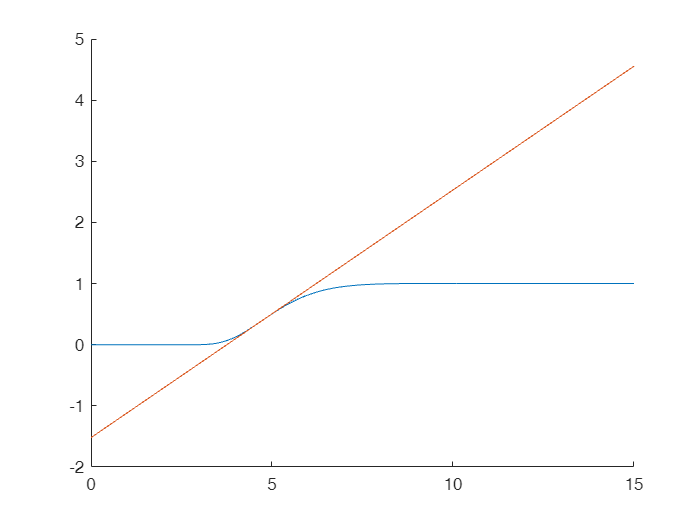

figure();
hold on 

max_slp = -time(midx)*max_slope+output_data(midx) +  max_slope*time;
plot(time,output_data);
plot(time,max_slp);
hold off

j = 1;
for i = 1:1501
    if max_slp(i) > 0
        temp(j) = (time(i));
        j = j+1;
    end 
end
L = temp(1)

L = 3.7600


for i = 1:1501
    if output_data(i) >= 0.63*max(output_data)
        temp2 = (time(i));
        break;
    end 
end
T_ar = temp2

T_ar = 5.3500

T = T_ar - L

T = 1.5900

K = max(output_data)

K = 1.0014

مدل چهار جزئی


% finding two random points 

d1 = output_data(450);
t1 = time(450);

d2 = output_data(i);
t2 = time(i);
figure();
points = [d1,d2];
p_times = [t1,t2]

p_times =     4.4900    5.3500


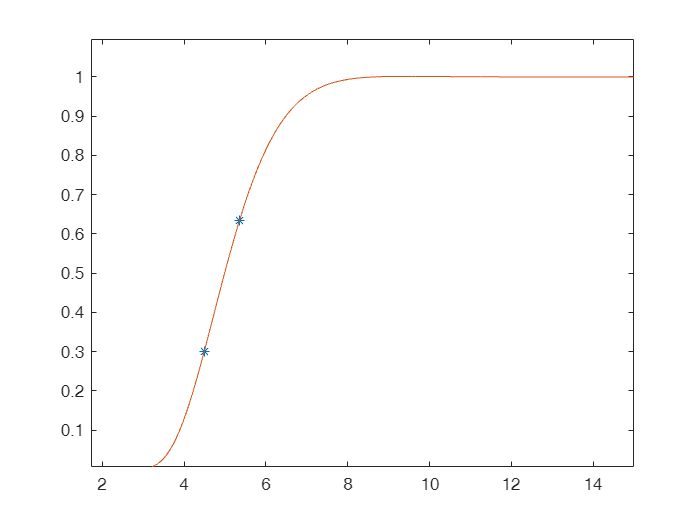

plot(p_times,points,"*");
hold on 
plot(time,output_data);
hold off

func = @(t_array)root(t_array,t1,t2,L,d1,d2,K);
t0 = [0.01,0.5];
t_array = fsolve(func,t0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


t_array

t_array =     0.1581    1.5901


using MATLAB ident

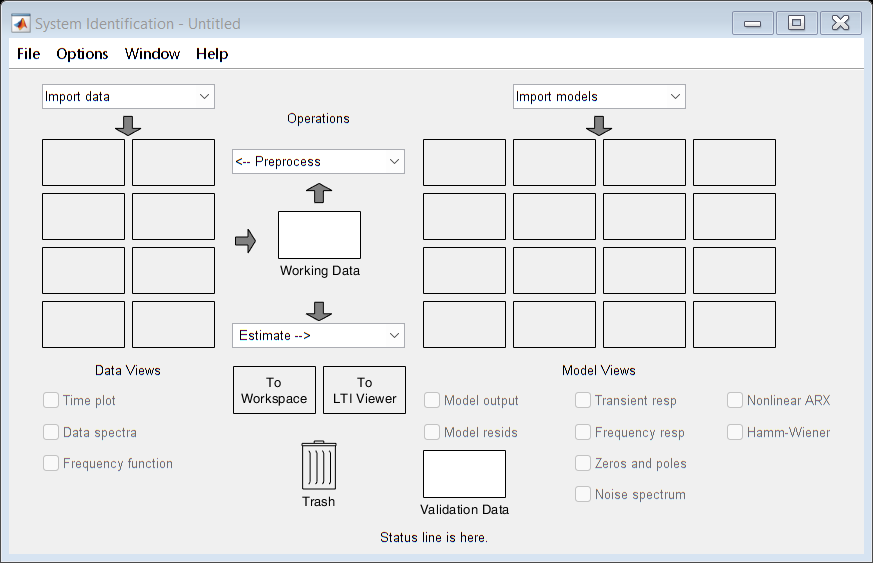

ident()

tf_D

tf_D =
  From input "u1" to output "y1":
          1.254
  ---------------------
  s^2 + 1.918 s + 1.255
 
Name: tf_D
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                            
Estimated using TFEST on time domain data "mydata".
Fit to estimation data: 99.06% (stability enforced)
FPE: 5.189e-06, MSE: 5.143e-06                     
 
Model Properties


id_tf = tf(tf_D);

Part 2 in simulink

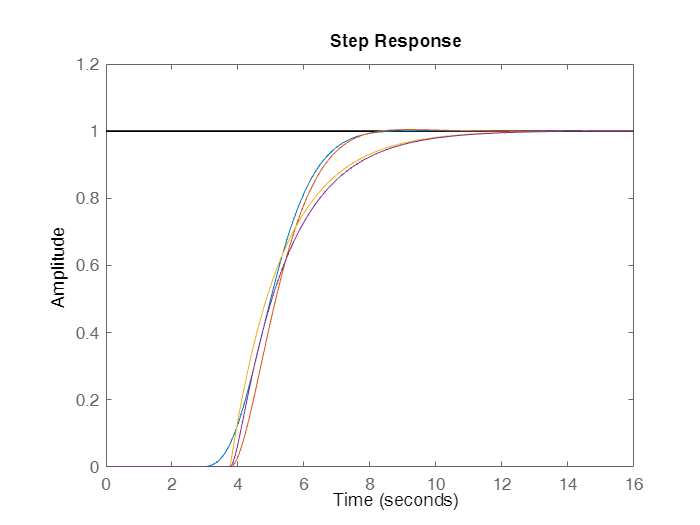

s = tf('s');
G3 = (K*exp(-(L*s)))/(1+T*s);
G4 = (K*exp(-(L*s)))/((1+t_array(1)*s)*(1+t_array(2)*s));
Gid = (1.254*exp(-(L*s)))/(s^2+1.918*s+1.255);
G_p = (131.8*(s+1)*exp(-2.5*s))/(((s+2.5)^4)*((s+1.5)^3));

figure();

step(G_p)
hold on 
step(Gid)
step(G3)
step(G4)
hold off

PID 

a = abs(-time(midx)*max_slope+output_data(midx))

a = 1.5195

L

L = 3.7600

function F = root(t_array,t1,t2,L,d1,d2,K) 
    F(1) = 1+(t_array(2)*exp(-(t1-L)/t_array(2))-t_array(1)*exp(-(t1-L)/t_array(1)))/(t_array(1)-t_array(2)) - d1/K;
    F(2) = 1+(t_array(2)*exp(-(t2-L)/t_array(2))-t_array(1)*exp(-(t2-L)/t_array(2)))/(t_array(1)-t_array(2)) - d2/K;
end

